# VPC miss analysis

## Import datasets

error False
varsToLoad = {'Psychos', 'Neurons', 'pi'};
session_NP = [264, 310, 345;17, 20, 23]

### Fix neurons VPCd 32

N = session_NP(1,1); %number of neurons
P = session_NP(2,1); %number of psychometrics files

loadedData = load('workspace.mat', varsToLoad{:});
Psychosd32 = loadedData.Psychos;
Neuronsd32 = loadedData.Neurons;
pid32 = loadedData.pi;

Neud32 = cell(N,1); Psyclean_d32 = cell(P,1);
for n = 1:N
    if pid32(n) == 1
        Neud32{n} = Neuronsd32{n}(Psychosd32{pid32(n)}.Trial < 145, :);
        Psyclean_d32{1} = Psychosd32{1}(Psychosd32{pid32(n)}.Trial < 145, :);
    else
        try
            Neud32{n} = Neuronsd32{n}(Psychosd32{pid32(n)}.Hits == 1, :);
            Neud32{n} = Neuronsd32{n};
        catch
            n
        end
    end
end

for p = 2:P
    Psyclean_d32{p} = Psychosd32{p};
end


### Align times and remove missing trails neurons VPCd 32

err = zeros(7,1);
i = 0;
for n = 1:N
    try
        Neud32{n} = Neud32{n}./30000 - Psyclean_d32{pid32(n)}.o3;
    catch
        i = i + 1;
        err(i) = n;
        n
    end
end

for n = 1:i
    Neud32{err(n)} = zeros(length(Psyclean_d32{pid32(err(n))}.o3),1);
end

### Fix neurons VPCi 32

N = session_NP(1,2); %number of neurons
P = session_NP(2,2); %number of psychometrics files

loadedData = load('workspace.mat', varsToLoad{:});
Psychosi32 = loadedData.Psychos;
Neuronsi32 = loadedData.Neurons;
pii32 = loadedData.pi;

Neui32 = cell(N,1); Psyclean_i32 = cell(P,1);
for n = 1:N
    if n == 15 || n == 190 %fix warnings
        n
    else
        try
            Neui32{n} = Neuronsi32{n}(Psychosi32{pii32(n)}.Hits == 1, :);
            Neui32{n} = Neuronsi32{n};
        catch
            n
        end
    end
end

for p = 1:P
    Psyclean_i32{p} = Psychosi32{p};
end

### Align times and remove missing trails neurons VPCi 32

err = zeros(6,1);
i = 0;
for n = 1:N
    try
        f = Neui32{n}./30000 - Psyclean_i32{pii32(n)}.o3;
    catch
        i = i + 1;
        err(i) = n;
        n
    end
end

for n = 1:i
    Neui32{err(n)} = zeros(length(Psyclean_i32{pii32(err(n))}.o3),1);
end

### Fix neurons VPCd 33

N = session_NP(1,3); %number of neurons
P = session_NP(2,3); %number of psychometrics files

loadedData = load('workspace.mat', varsToLoad{:});
Psychosd33 = loadedData.Psychos;
Neuronsd33 = loadedData.Neurons;
pid33 = AllPsico;

Neud33 = cell(N,1); Psyclean_d33 = cell(P+8,1);

for n = 1:N
    if n == 22 || n == 24 %fix warnings
        Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Trial < 123, :);
        pid33(n) = P + 1;
    elseif n == 58 || n == 99
        n
    elseif n == 100 || n == 101 || n == 102 || n == 103 || n == 110 || n == 111 %97-111
        Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Trial < 150 & Psychosd33{pid33(n)}.Trial > 60, :);
        pid33(n) = P + 2;

    elseif n == 177
        Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Trial > 40, :);
        pid33(n) = P + 3;

    elseif n == 122
        Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Trial < 75, :);
        pid33(n) = P + 4;

    elseif n == 150 || n == 151 || n == 152
        Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Trial < 50, :);
        pid33(n) = P + 5;

    elseif n == 176
        Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Trial > 40, :);
        pid33(n) = P + 6;
    elseif n == 230 || n == 231
        Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Trial > 70, :);
        pid33(n) = P + 7;
    elseif n == 295
        Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Trial < 130, :);
        pid33(n) = P + 8;

    else
        try
            Neud33{n} = Neuronsd33{n}(Psychosd33{pid33(n)}.Hits == 1, :);
            Neud33{n} = Neuronsd33{n};
        catch
            n
        end
    end
end

%fix psychos
Psyclean_d33{P+1} = Psychosd33{2}(Psychosd33{2}.Trial < 123, :);
Psyclean_d33{P+2} = Psychosd33{8}(Psychosd33{8}.Trial < 150 & Psychosd33{8}.Trial > 60, :);
Psyclean_d33{P+3} = Psychosd33{9}(Psychosd33{9}.Trial < 40, :);
Psyclean_d33{P+4} = Psychosd33{10}(Psychosd33{10}.Trial < 75, :);
Psyclean_d33{P+5} = Psychosd33{13}(Psychosd33{13}.Trial < 50, :);
Psyclean_d33{P+6} = Psychosd33{15}(Psychosd33{15}.Trial > 40, :);
Psyclean_d33{P+7} = Psychosd33{18}(Psychosd33{18}.Trial > 70, :);
Psyclean_d33{P+8} = Psychosd33{21}(Psychosd33{21}.Trial < 130, :);


for p = 1:P
    Psyclean_d33{p} = Psychosd33{p};
end

## Frequency

mini = -7; pas = 0.02; maxi = 4;
tv = mini:pas:maxi;
lentv = length(tv);
Frd32 = cell(264, 1); Fri32 = cell(310, 1); Frd33 = cell(345, 1);
for n = 1:session_NP(1,1)
    Frd32{n} = freq(Neud32{n}, pas, 0.2, mini, maxi);
end
for n = 1:session_NP(1,2)
    Fri32{n} = freq(Neui32{n}, pas, 0.2, mini, maxi);
end
for n = 1:session_NP(1,3)
    Frd33{n} = freq(Neud33{n}, pas, 0.2, mini, maxi);
end

### Merge datasets

N = 919;
P = 68;
Fr = [Frd32;Fri32;Frd33];
Psycur = [Psyclean_d32;Psyclean_i32;Psyclean_d33];
pi = [pid32;pii32;pid33];
pi(265:end) = pi(265:end) + 17;
pi(575:end) = pi(575:end) + 20;

## MU & FA Trials

P_noextra = 60;

Bottons = ["Aud","NoS","Tac"];
color_class = containers.Map(Bottons,["#5994FF", "black", "#FF9933"]);
MU_n = zeros(2,P_noextra);
False_alarm = zeros(2,P_noextra);
Miss = zeros(2,P_noextra);

for p = 1:P_noextra
    MU_n(1,p) = sum(Psycur{p}.SelectedButton == 1 & Psycur{p}.CorrectButton == 3);
    MU_n(2,p) = sum(Psycur{p}.SelectedButton == 3 & Psycur{p}.CorrectButton == 1);
    False_alarm(1,p) = sum(Psycur{p}.SelectedButton == 1 & Psycur{p}.CorrectButton == 2);
    False_alarm(2,p) = sum(Psycur{p}.SelectedButton == 3 & Psycur{p}.CorrectButton == 2);
    Miss(1,p) = sum(Psycur{p}.SelectedButton == 2 & Psycur{p}.CorrectButton == 1);
    Miss(2,p) = sum(Psycur{p}.SelectedButton == 2 & Psycur{p}.CorrectButton == 3);
end

subplot(3,1,1)
plot(MU_n(1,:), "Marker","o","LineStyle","none", "Color",color_class("Aud"),"MarkerFaceColor",color_class("Aud"))
hold on
plot(MU_n(2,:), "Marker","^","LineStyle","none", "Color",color_class("Tac"),"MarkerFaceColor",color_class("Tac"))
ylim([0,15])
legend(["Selected button Acoustic","Selected button Tactile"])
ylabel("Number of MU trials")
hold off

subplot(3,1,2)
plot(Miss(1,:), "Marker","o","LineStyle","none", "Color",color_class("Aud"),"MarkerFaceColor",color_class("Aud"))
hold on
plot(Miss(2,:), "Marker","^","LineStyle","none", "Color",color_class("Tac"),"MarkerFaceColor",color_class("Tac"))
%ylim([0,15])
legend(["Acoustic miss","Tactile miss"])
ylabel("Number of Miss trials")
hold off

subplot(3,1,3)
plot(False_alarm(1,:), "Marker","o","LineStyle","none", "Color",color_class("Aud"),"MarkerFaceColor",color_class("Aud"))
hold on
plot(False_alarm(2,:), "Marker","^","LineStyle","none", "Color",color_class("Tac"),"MarkerFaceColor",color_class("Tac"))
legend(["Selected button Acoustic","Selected button Tactile"])
ylim([0,15])
xlabel("Session number")
ylabel("Number of FA trials")
hold off

Psyco_matrix = zeros(3,3,P_noextra); % Tac, Aud, NoS

for p = 1:P_noextra
    n_t = Psycur{p}.Trial(end);
    Psyco_matrix(1,1,p) = sum(Psycur{p}.SelectedButton == 3 & Psycur{p}.CorrectButton == 3) / n_t;
    Psyco_matrix(2,2,p) = sum(Psycur{p}.SelectedButton == 1 & Psycur{p}.CorrectButton == 1) / n_t;
    Psyco_matrix(3,3,p) = sum(Psycur{p}.SelectedButton == 2 & Psycur{p}.CorrectButton == 2) / n_t;

    Psyco_matrix(2,1,p) = MU_n(1,p) / n_t;    
    Psyco_matrix(1,2,p) = MU_n(2,p) / n_t;

    Psyco_matrix(3,2,p) = False_alarm(1,p) / n_t;    
    Psyco_matrix(3,1,p) = False_alarm(2,p) / n_t;

    Psyco_matrix(2,3,p) = Miss(1,p) / n_t;    
    Psyco_matrix(1,3,p) = Miss(2,p) / n_t;
end

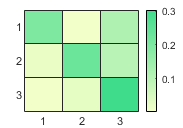

n = 256; % Number of colors
greenMap = [linspace(0.9568, 0.2470, n)', linspace(1, 0.8666, n)', linspace(0.7882, 0.5490, n)']; 

heatmap(mean(Psyco_matrix,3,"omitnan"))
colormap(greenMap);
colorbar()
saveas(gcf, "Psyco_matrix.svg")

## Choice Probability

Import coding neurons

P05IM = load('workspace2.mat', 'P05IM');
P05IM = P05IM.P05IM;

i = tv(326); e = tv(526);
wind = tv >= i & tv <= e;
lenwin = sum(wind);
CP = nan(N, lenwin);

for n = 1:N
    try
        ed = linspace(min(Fr{n}(:,wind),[],"all"), ...
            max(Fr{n}(:,wind),[],"all"),10);
        for t1 = 1:lenwin
            t = t1 + 326;
            if pi(n) <= P_noextra && P05IM(n,t1) == 1 && Miss(2,pi(n)) >= 5 %False_alarm(1,pi(n)) >= 5

                %             ed = linspace(min([Fr{n}(:,t),Fr{n}(:,tv >= -1 & tv < 0)],[],"all"), ...
                %                 max([Fr{n}(:,t),Fr{n}(:,tv >= -1 & tv < 0)],[],"all"),10);


                %                 cond1 = Psycur{pi(n)}.SelectedButton == 2 & ...
                %                     Psycur{pi(n)}.CorrectButton == 2;
                %                 cond2 = Psycur{pi(n)}.SelectedButton == 1 & ...
                %                     Psycur{pi(n)}.CorrectButton == 2;
                cond1 = Psycur{pi(n)}.SelectedButton == 2 & ...
                    Psycur{pi(n)}.CorrectButton == 3 & Psycur{pi(n)}.AmpStim3 < 10;
                cond2 = Psycur{pi(n)}.SelectedButton == 3 & ...
                    Psycur{pi(n)}.CorrectButton == 3 & Psycur{pi(n)}.AmpStim3 < 10;

                Pshit = histcounts(Fr{n}(cond1, t), ...
                    ed,"Normalization","probability");
                PsFAaud = histcounts(Fr{n}(cond2, t), ...
                    ed,"Normalization","probability");

                cPshit = [0,cumsum(Pshit)];
                cPsFAaud = [0,cumsum(PsFAaud)];

                CP(n,t1) = trapz(cPshit,cPsFAaud);
            end
        end
    catch
        n
    end
end

#### Plotting

absCP = abs(CP-0.5) + 0.5;
meanCP = mean(absCP, 'omitnan');
clf
hold on
plot(tv(wind), meanCP, "Color","#ffb703", 'LineWidth', 1.5)
plot(tv(wind), prctile(absCP, 5), "Color","#ffb703", 'LineWidth', 1.5, "LineStyle",":")
plot(tv(wind), prctile(absCP, 95), "Color","#ffb703", 'LineWidth', 1.5, "LineStyle",":")

xlabel("time")
xlim([0.1,3.5])
ylabel("Choice Probability")
ylim([0.5,1])
hold off

ti = find(tv(wind) == 0.5);
subplot(2,1,1)
histogram(CP(:,ti), "FaceColor","#ffb703")
hold on
plot([0.5,0.5],[0,50],"LineStyle","--","Color","k")
hold off
xlim([0,1])
ylim([0,50])
ylabel("N, t = 0.5")

ti = find(tv(wind) == 1.5);
subplot(2,1,2)
histogram(CP(:,ti), "FaceColor","#ffb703")
hold on
plot([0.5,0.5],[0,50],"LineStyle","--","Color","k")
hold off
xlim([0,1])
ylim([0,50])
xlabel("CP")
ylabel("N, t = 1.5")


plot(tv(wind), sum(~isnan(CP)), 'k')
xlabel("time")
xlim([0.1,3.5])
ylabel("N")

Plot of individual neurons Miss

example_neurons = [125,162,107+575,138+575,17,41+265];
for n = example_neurons
    figure(a)
    clf, hold off
    subplot(2,1,1)
    hold on
    plot(tv,mean(Fr{n}(Psycur{pi(n)}.AmpStim3 == 0 & ...
        Psycur{pi(n)}.Hits == 1,:)),"Color",color_class("NoS"))
    plot(tv,mean(Fr{n}(Psycur{pi(n)}.AmpStim3 < 10 & ...
        Psycur{pi(n)}.AmpStim3 > 0 & ...
        Psycur{pi(n)}.Hits == 1,:)),"Color",color_class("Tac"))
    plot(tv,mean(Fr{n}(Psycur{pi(n)}.AmpStim3 < 10 & ...
        Psycur{pi(n)}.AmpStim3 > 0 & ...
        Psycur{pi(n)}.SelectedButton == 2 & ...
        Psycur{pi(n)}.CorrectButton == 3,:)),"Color","r")
    legend("NoS","Tac","Miss")
    title(["Neuron "; num2str(n)])
    xlim([-0.5,3.5])
    ylabel("Fr")
    subplot(2,1,2)
    plot(tv(wind), CP(n,:), "Color","#ffb703", 'LineWidth', 1.5)
    hold on
    plot(tv(wind), 0.5 * ones(sum(wind)),"Color","k","LineStyle","--")
    hold off
    xlim([-0.5,3.5])
    ylim([0,1])
    ylabel("CP")
    xlabel("Time")

    a = a + 1;
end

FA

a = 1;
for n = example_neurons

    figure(a)
    clf, hold off
    subplot(2,1,1)
    hold on
    plot(tv,mean(Fr{n}(Psycur{pi(n)}.SelectedButton == 2 & ...
        Psycur{pi(n)}.CorrectButton == 2,:)),"Color",color_class("NoS"))
    plot(tv,mean(Fr{n}(Psycur{pi(n)}.SelectedButton == 1 & ...
        Psycur{pi(n)}.CorrectButton == 2,:)),"Color",color_class("Aud"))
    xlim([-0.5,3.5])
    legend("CR","FA")
    title(["Neuron "; num2str(n)])
    ylabel("Fr")
    subplot(2,1,2)
    plot(tv(wind), CP(n,:), "Color","#ffb703", 'LineWidth', 1.5)
    hold on
    plot(tv(wind), 0.5 * ones(sum(wind)),"Color","k","LineStyle","--")
    hold off
    xlim([-0.5,3.5])
    ylim([0,1])
    ylabel("CP")
    xlabel("Time")

    a = a + 1;
end

### Z-score CP

#### Tac

Calculate z scores of hits and miss trails

Zscore_hits = nan(N, lenwin);
Zscore_miss = nan(N, lenwin);
code_sign = nan(N, lenwin);

for n = 1:N
    try
        Frmean = mean(Fr{n}(:,tv > -1 & tv < 0), 'all','omitnan');
        Frstd = std(reshape(Fr{n}(:,tv > -1 & tv < 0),1,[]),'omitnan');
        cond1 = Psycur{pi(n)}.SelectedButton == 2 & ...
            Psycur{pi(n)}.CorrectButton == 3 & Psycur{pi(n)}.AmpStim3 < 10;
        cond2 = Psycur{pi(n)}.SelectedButton == 3 & ...
            Psycur{pi(n)}.CorrectButton == 3 & Psycur{pi(n)}.AmpStim3 < 10;
        NoS_hit = Psycur{pi(n)}.SelectedButton == 2 & ...
                    Psycur{pi(n)}.CorrectButton == 2;
        Tac_hit = Psycur{pi(n)}.SelectedButton == 3 & ...
                    Psycur{pi(n)}.CorrectButton == 3;

        for t1 = 1:lenwin
            t = t1 + 326;
            if pi(n) <= P_noextra && P05IM(n,t1) == 1 && Miss(2,pi(n)) >= 5
                code_sign(n,t1) = sign(mean(Fr{n}(Tac_hit,t),'omitnan') - ...
                    mean(Fr{n}(NoS_hit,t),'omitnan'));

                Zscore_miss(n,t1) = mean((Fr{n}(cond1,t) - Frmean) ./ Frstd,'omitnan');
                Zscore_hits(n,t1) = mean((Fr{n}(cond2,t) - Frmean) ./ Frstd,'omitnan');
            end
        end
    catch
        n
    end
end

Plot distributions and CP

CP_zscore = nan(1,lenwin);
a = 1;
%ed = linspace(-2,2, 20);
ed = logspace(-0.8,1, 10);
ed = [-flip(ed),ed];
edm = (ed(1:end-1) + ed(2:end)) / 2;

Zscore_hits_s = code_sign .* Zscore_hits;
Zscore_miss_s = code_sign .* Zscore_miss;

for t1 = 1:lenwin
    valid_hits = Zscore_hits_s(~isnan(Zscore_hits(:,t1)),t1);
    valid_miss = Zscore_miss_s(~isnan(Zscore_miss(:,t1)),t1);

    Pshit = histcounts(valid_hits, ...
        ed,"Normalization","probability");
    Psmiss = histcounts(valid_miss, ...
        ed,"Normalization","probability");

    cPshit = [0,cumsum(Pshit)];
    cPsmiss = [0,cumsum(Psmiss)];

    CP_zscore(t1) = trapz(cPshit,cPsmiss);

    if rem(t1,50) == 0
        subplot(4,1,a)
          
        plot(edm, Pshit,"Color","green")
        hold on
        plot(edm, Psmiss,"Color","red")
        hold off
        ylabel("P(z)")
        xlim([-8,8])

        title("t = " + num2str(tv(t1+326)))
        a = a + 1;
    end
end
legend('P(z|hit)','P(z|miss)',"Location","west")
xlabel("z score")
%saveas(gcf, "Pz_tac.svg")

Bootstrap

n_boot = 1000;
CP_z_boot = nan(n_boot,lenwin);

for t1 = 1:lenwin
    valid_n = ~isnan(Zscore_miss(:,t1));
    valid_indx = find(valid_n);

    if sum(valid_n) > 10
        for b = 1:n_boot
            
            r = valid_indx(randi(length(valid_indx), 1, sum(valid_n)));

            Pshit = histcounts(Zscore_hits_s(r,t1), ...
                ed,"Normalization","probability");
            Psmiss = histcounts(Zscore_miss_s(r,t1), ...
                ed,"Normalization","probability");

            cPshit = [0,cumsum(Pshit)];
            cPsmiss = [0,cumsum(Psmiss)];

            CP_z_boot(b,t1) = trapz(cPshit,cPsmiss);

        end
    end
end


std_CP_z_boot = std(CP_z_boot, 'omitnan');
clf, hold off
plot(tv(wind),CP_zscore,"Color","#ffb703", 'LineWidth', 1.5)
hold on
plot(tv(wind), 0.5 * ones(sum(wind)),"Color","k","LineStyle","--")
plot(tv(wind), CP_zscore + 2*std_CP_z_boot,"Color","#ffb703","LineStyle","--")
plot(tv(wind), CP_zscore - 2*std_CP_z_boot,"Color","#ffb703","LineStyle","--")
hold off
xlim([0.1,3.5])
ylim([0,1])
ylabel("CP")
xlabel("Time")
%saveas(gcf, "CPz_tac.svg")

#### Aud

Calculate z scores of hits and miss trails

Zscore_hits_aud = nan(N, lenwin);
Zscore_miss_aud = nan(N, lenwin);
code_sign_aud = nan(N, lenwin);

for n = 1:N
    try
        Frmean = mean(Fr{n}(:,tv > -1 & tv < 0), 'all','omitnan');
        Frstd = std(reshape(Fr{n}(:,tv > -1 & tv < 0),1,[]),'omitnan');
        cond1 = Psycur{pi(n)}.SelectedButton == 2 & ...
            Psycur{pi(n)}.CorrectButton == 1 & Psycur{pi(n)}.AudStim3 < 0.2;
        cond2 = Psycur{pi(n)}.SelectedButton == 1 & ...
            Psycur{pi(n)}.CorrectButton == 1 & Psycur{pi(n)}.AudStim3 < 0.2;
        NoS_hit = Psycur{pi(n)}.SelectedButton == 2 & ...
                    Psycur{pi(n)}.CorrectButton == 2;
        Aud_hit = Psycur{pi(n)}.SelectedButton == 1 & ...
                    Psycur{pi(n)}.CorrectButton == 1;

        for t1 = 1:lenwin
            t = t1 + 326;
            if pi(n) <= P_noextra && P05IM(n,t1) == 1 && Miss(1,pi(n)) >= 5
                code_sign_aud(n,t1) = sign(mean(Fr{n}(Aud_hit,t),'omitnan') - ...
                    mean(Fr{n}(NoS_hit,t),'omitnan'));

                Zscore_miss_aud(n,t1) = mean((Fr{n}(cond1,t) - Frmean) ./ Frstd,'omitnan');
                Zscore_hits_aud(n,t1) = mean((Fr{n}(cond2,t) - Frmean) ./ Frstd,'omitnan');
            end
        end
    catch
        n
    end
end

Plot distributions and CP

CP_zscore_aud = nan(1,lenwin);
a = 1;
%ed = linspace(-2,2, 20);
ed = logspace(-0.8,1, 10);
ed = [-flip(ed),ed];
edm = (ed(1:end-1) + ed(2:end)) / 2;

Zscore_hits_s = code_sign_aud .* Zscore_hits_aud;
Zscore_miss_s = code_sign_aud .* Zscore_miss_aud;

for t1 = 1:lenwin
    valid_hits = Zscore_hits_s(~isnan(Zscore_hits_aud(:,t1)),t1);
    valid_miss = Zscore_miss_s(~isnan(Zscore_miss_aud(:,t1)),t1);

    Pshit = histcounts(valid_hits, ...
        ed,"Normalization","probability");
    Psmiss = histcounts(valid_miss, ...
        ed,"Normalization","probability");

    cPshit = [0,cumsum(Pshit)];
    cPsmiss = [0,cumsum(Psmiss)];

    CP_zscore_aud(t1) = trapz(cPshit,cPsmiss);

    if rem(t1,50) == 0
        subplot(4,1,a)
          
        plot(edm, Pshit,"Color","green")
        hold on
        plot(edm, Psmiss,"Color","red")
        hold off
        ylabel("P(z)")
        xlim([-8,8])

        title("t = " + num2str(tv(t1+326)))
        a = a + 1;
    end
end
legend('P(z|hit)','P(z|miss)',"Location","west")
xlabel("z score")
%saveas(gcf, "Pz_aud.svg")

Bootstrap

n_boot = 1000;
CP_z_boot = nan(n_boot,lenwin);

for t1 = 1:lenwin
    valid_n = ~isnan(Zscore_miss_aud(:,t1));
    valid_indx = find(valid_n);

    if sum(valid_n) > 10
        for b = 1:n_boot
            
            r = valid_indx(randi(length(valid_indx), 1, sum(valid_n)));

            Pshit = histcounts(Zscore_hits_s(r,t1), ...
                ed,"Normalization","probability");
            Psmiss = histcounts(Zscore_miss_s(r,t1), ...
                ed,"Normalization","probability");

            cPshit = [0,cumsum(Pshit)];
            cPsmiss = [0,cumsum(Psmiss)];

            CP_z_boot(b,t1) = trapz(cPshit,cPsmiss);
        end
    end
end


std_CP_z_boot = std(CP_z_boot, 'omitnan');
clf, hold off
plot(tv(wind),CP_zscore_aud,"Color","#ffb703", 'LineWidth', 1.5)
hold on
plot(tv(wind), 0.5 * ones(sum(wind)),"Color","k","LineStyle","--")
plot(tv(wind), CP_zscore_aud + 2*std_CP_z_boot,"Color","#ffb703","LineStyle","--")
plot(tv(wind), CP_zscore_aud - 2*std_CP_z_boot,"Color","#ffb703","LineStyle","--")
hold off
xlim([0.1,3.5])
ylim([0,1])
ylabel("CP")
xlabel("Time")
%saveas(gcf, "CPz_aud.svg")

### Tac vs Aud

Import significant coding neurons 

loadedData = load('workspace2.mat', 'IMpairs');
IMpairs = loadedData.IMpairs;

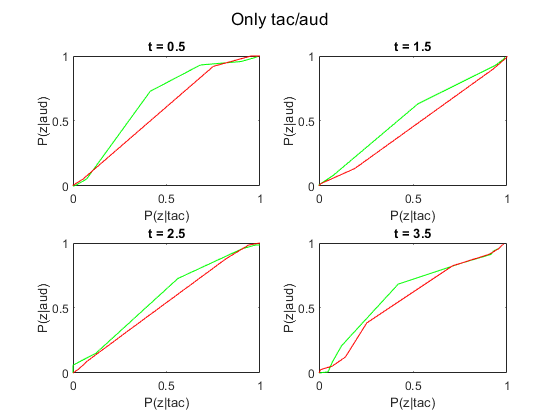

Zscore_hits_s = code_sign .* Zscore_hits;
Zscore_miss_s = code_sign .* Zscore_miss;

Zscore_hits_s_aud = code_sign_aud .* Zscore_hits_aud;
Zscore_miss_s_aud = code_sign_aud .* Zscore_miss_aud;

%only significant tac_aud
Zscore_hits_s(~IMpairs(:,:,1)) = nan;
Zscore_miss_s(~IMpairs(:,:,1)) = nan;
Zscore_hits_s_aud(~IMpairs(:,:,1)) = nan;
Zscore_miss_s_aud(~IMpairs(:,:,1)) = nan;

CP_zscore_tac_aud = nan(2,lenwin); %hit, miss

ed = linspace(-5,5,10); %1
a = 1;
for t1 = 1:lenwin
    valid_hits = Zscore_hits_s(~isnan(Zscore_hits_s(:,t1)),t1);
    valid_miss = Zscore_miss_s(~isnan(Zscore_miss_s(:,t1)),t1);

    valid_hits_aud = Zscore_hits_s_aud(~isnan(Zscore_hits_s_aud(:,t1)),t1);
    valid_miss_aud = Zscore_miss_s_aud(~isnan(Zscore_miss_s_aud(:,t1)),t1);

    Pshit = histcounts(valid_hits, ...
        ed,"Normalization","probability");
    Psmiss = histcounts(valid_miss, ...
        ed,"Normalization","probability");

    Pshit_aud = histcounts(valid_hits_aud, ...
        ed,"Normalization","probability");
    Psmiss_aud = histcounts(valid_miss_aud, ...
        ed,"Normalization","probability");

    cPshit = [0,cumsum(Pshit)];
    cPsmiss = [0,cumsum(Psmiss)];

    cPshit_aud = [0,cumsum(Pshit_aud)];
    cPsmiss_aud = [0,cumsum(Psmiss_aud)];
    
    CP_zscore_tac_aud(1,t1) = trapz(cPshit,cPshit_aud);
    CP_zscore_tac_aud(2,t1) = trapz(cPsmiss,cPsmiss_aud);

    if rem(t1,50) == 0
        subplot(2,2,a)
          
        %plot(edm, Pshit,"Color",color_class("Tac"))
        plot(cPshit, cPshit_aud,"Color","green")
        hold on
        %plot(edm, Pshit_aud,"Color",color_class("Aud"))
        plot(cPsmiss, cPsmiss_aud,"Color","red")
        hold off
        xlabel("P(z|tac)")
        ylabel("P(z|aud)")
        %xlim([-8,8])

        title("t = " + num2str(tv(t1+326)))
        a = a + 1;
    end
end
sgtitle("Only tac/aud")

Bootstrap

n_boot = 1000;
CP_z_boot = nan(2,lenwin,n_boot);

for t1 = 1:lenwin
    valid_n = ~isnan(Zscore_miss_s(:,t1));
    valid_indx = find(valid_n);

    valid_n_aud = ~isnan(Zscore_miss_s_aud(:,t1));
    valid_indx_aud = find(valid_n_aud);

    if sum(valid_n) > 10 && sum(valid_n_aud) > 10
        for b = 1:n_boot
            
            r = valid_indx(randi(length(valid_indx), 1, sum(valid_n)));
            r_aud = valid_indx_aud(randi(length(valid_indx_aud), 1, sum(valid_n_aud)));
            
            Pshit = histcounts(Zscore_hits_s(r,t1), ...
            ed,"Normalization","probability");
            Psmiss = histcounts(Zscore_miss_s(r,t1), ...
            ed,"Normalization","probability");
            
            Pshit_aud = histcounts(Zscore_hits_s_aud(r_aud,t1), ...
            ed,"Normalization","probability");
            Psmiss_aud = histcounts(Zscore_miss_s_aud(r_aud,t1), ...
            ed,"Normalization","probability");
            
            cPshit = [0,cumsum(Pshit)];
            cPsmiss = [0,cumsum(Psmiss)];
            
            cPshit_aud = [0,cumsum(Pshit_aud)];
            cPsmiss_aud = [0,cumsum(Psmiss_aud)];
            
            CP_z_boot(1,t1,b) = trapz(cPshit,cPshit_aud);
            CP_z_boot(2,t1,b) = trapz(cPsmiss,cPsmiss_aud);
        end
    end
end

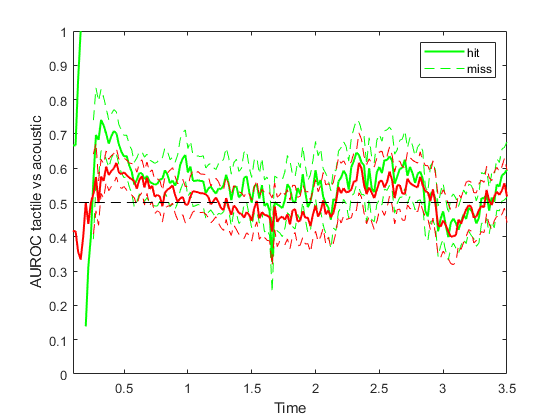

std_CP_z_boot = std(CP_z_boot, 0, 3, 'omitnan');
clf, hold off
plot(tv(wind),CP_zscore_tac_aud(1,:),"Color","green", 'LineWidth', 1.5)
hold on
plot(tv(wind), CP_zscore_tac_aud(1,:) + 2*std_CP_z_boot(1,:),"Color","green","LineStyle","--")
plot(tv(wind), CP_zscore_tac_aud(1,:) - 2*std_CP_z_boot(1,:),"Color","green","LineStyle","--")

plot(tv(wind),CP_zscore_tac_aud(2,:),"Color","red", 'LineWidth', 1.5)
plot(tv(wind), CP_zscore_tac_aud(2,:) + 2*std_CP_z_boot(2,:),"Color","red","LineStyle","--")
plot(tv(wind), CP_zscore_tac_aud(2,:) - 2*std_CP_z_boot(2,:),"Color","red","LineStyle","--")

plot(tv(wind), 0.5 * ones(sum(wind)),"Color","k","LineStyle","--")

hold off
legend('hit','miss')
xlim([0.1,3.5])
ylim([0,1])
ylabel("AUROC tactile vs acoustic")
xlabel("Time")

%saveas(gcf, "AUROC_t_a_sig.svg")

## Mutual Information

#### Individual Neurons

i = tv(326); e = tv(526);
wind = tv >= i & tv <= e;
lenwin = sum(wind);
Ps = [1/3, 1/3, 1/3];

IM_hits = nan(N,lenwin);
IM_miss = nan(N,lenwin);


for n = 1:N
    try
        for t1 = 1: lenwin
            t = t1 + 325;
            ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);

            %% Hits
            hittac = Psycur{pi(n)}.AmpStim3 ~= 0. & Psycur{pi(n)}.AudStim3 == 0. & ...
                Psycur{pi(n)}.Hits == 1;
            hitaud = Psycur{pi(n)}.AmpStim3 == 0. & Psycur{pi(n)}.AudStim3 ~= 0.& ...
                Psycur{pi(n)}.Hits == 1;
            RCtrial = Psycur{pi(n)}.AmpStim3 == 0. & Psycur{pi(n)}.AudStim3 == 0.& ...
                Psycur{pi(n)}.Hits == 1;

            Pt = histcounts(Fr{n}(Psycur{pi(n)}.Hits == 1,t),ed,"Normalization","probability");

            Psr1 = histcounts(Fr{n}(hittac,t), ed,"Normalization","probability");
            Psr2 = histcounts(Fr{n}(hitaud,t), ed,"Normalization","probability");
            Psr3 = histcounts(Fr{n}(RCtrial,t), ed,"Normalization","probability");
            IM_hits(n,t1) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan") + Ps(3)*sum(Psr3.*log2(Psr3./Pt),"omitnan");

            %% Miss
            misstac = Psycur{pi(n)}.AmpStim3 ~= 0. & Psycur{pi(n)}.AudStim3 == 0. & ...
                Psycur{pi(n)}.Hits == 0;
            missaud = Psycur{pi(n)}.AmpStim3 == 0. & Psycur{pi(n)}.AudStim3 ~= 0.& ...
                Psycur{pi(n)}.Hits == 0;

            Pt = histcounts(Fr{n}(misstac | missaud | RCtrial,t),ed,"Normalization","probability");

            Psr1 = histcounts(Fr{n}(misstac,t), ed,"Normalization","probability");
            Psr2 = histcounts(Fr{n}(missaud,t), ed,"Normalization","probability");
            IM_miss(n,t1) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan") + Ps(3)*sum(Psr3.*log2(Psr3./Pt),"omitnan");
        end
    catch
        n
    end
end

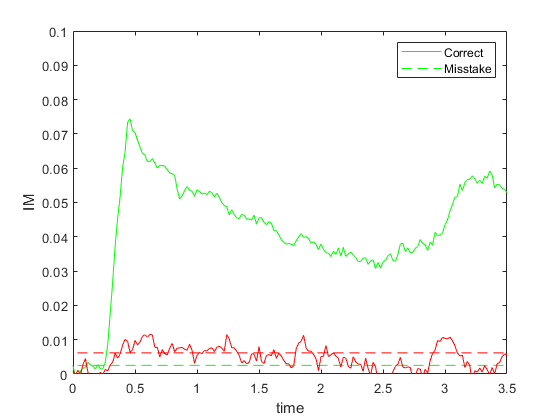

meanIM_hits = mean(IM_hits,'omitnan') - mean(IM_hits(:,tv(wind) > -0.5 & tv(wind) < 0),"all",'omitnan');
std_hit = std(mean(IM_hits(:,tv(wind) > -0.5 & tv(wind) < 0),'omitnan'),[],'omitnan');
meanIM_miss = mean(IM_miss,'omitnan') - mean(IM_miss(:,tv(wind) > -0.5 & tv(wind) < 0),"all",'omitnan');
std_miss = std(mean(IM_miss(:,tv(wind) > -0.5 & tv(wind) < 0),'omitnan'),[],"all",'omitnan');
clf, hold off
plot(tv(wind),meanIM_hits,"Color","green")
hold on
plot(tv(wind),3*std_hit*ones(lenwin,1),"Color","green","LineStyle","--")
plot(tv(wind),meanIM_miss,"Color","red")
plot(tv(wind),3*std_miss*ones(lenwin,1),"Color","red","LineStyle","--")
xlabel("time")
ylabel("IM")
xlim([0,3.5])
ylim([0,0.1])
legend("Correct","Misstake")
saveas(gcf, "mean_IM_mod.svg")
hold off

#### Z score

Calculate z scores of hits and miss trails for decision and stimulus

Zscore_hits_dec = nan(3, N, lenwin); % Aud, NoS, Tac
Zscore_miss_dec = nan(3, N, lenwin);
Zscore_hits_stim = nan(5, N, lenwin); % subAud, supAud, NoS, subTac, supTac
Zscore_miss_stim = nan(5, N, lenwin);

for n = 1:N
    try
        Frmean = mean(Fr{n}(:, tv > -1 & tv < 0), 'all', 'omitnan');
        Frstd = std(reshape(Fr{n}(:, tv > -1 & tv < 0), 1, []), 'omitnan');

        pc = Psycur{pi(n)};
        % Decision conditions: hits and misses
        dec_conds = [pc.Hits == 1 & pc.SelectedButton == 1, ...
                     pc.Hits == 1 & pc.SelectedButton == 2, ...
                     pc.Hits == 1 & pc.SelectedButton == 3];
        dec_conds_miss = [pc.Hits == 0 & pc.SelectedButton == 1, ...
                          pc.Hits == 0 & pc.SelectedButton == 2, ...
                          pc.Hits == 0 & pc.SelectedButton == 3];

        % Stim conditions: hits and misses
        stim_conds = [pc.Hits == 1 & pc.AudStim3 < 0.2 & pc.AudStim3 > 0, ...
                      pc.Hits == 1 & pc.AudStim3 >= 0.2, ...
                      pc.Hits == 1 & pc.AudStim3 == 0 & pc.AmpStim3 == 0, ...
                      pc.Hits == 1 & pc.AmpStim3 < 10 & pc.AmpStim3 > 0, ...
                      pc.Hits == 1 & pc.AmpStim3 > 10];
        stim_conds_miss = [pc.Hits == 0 & pc.AudStim3 < 0.2 & pc.AudStim3 > 0, ...
                           pc.Hits == 0 & pc.AudStim3 > 0.2, ...
                           pc.Hits == 1 & pc.AudStim3 == 0 & pc.AmpStim3 == 0, ...
                           pc.Hits == 0 & pc.AmpStim3 < 10 & pc.AmpStim3 > 0, ...
                           pc.Hits == 0 & pc.AmpStim3 >= 10];

        for t1 = 1:lenwin
            t = t1 + 326;
            if pi(n) <= P_noextra && P05IM(n, t1) == 1 && Miss(2, pi(n)) >= 5
                % Decision Z-scores
                for i = 1:3
                    Zscore_hits_dec(i, n, t1) = mean((Fr{n}(dec_conds(:,i), t) - Frmean) ./ Frstd, 'omitnan');
                    Zscore_miss_dec(i, n, t1) = mean((Fr{n}(dec_conds_miss(:,i), t) - Frmean) ./ Frstd, 'omitnan');
                end
                % Stimulus Z-scores
                for i = 1:5
                    Zscore_hits_stim(i, n, t1) = mean((Fr{n}(stim_conds(:,i), t) - Frmean) ./ Frstd, 'omitnan');
                    Zscore_miss_stim(i, n, t1) = mean((Fr{n}(stim_conds_miss(:,i), t) - Frmean) ./ Frstd, 'omitnan');
                end
            end
        end
    catch
        n
    end
end

n = 594

Signed Z-score

Zscore_hits_dec_s = Zscore_hits_dec; 
Zscore_miss_dec_s = Zscore_miss_dec;
Zscore_hits_stim_s = Zscore_hits_stim; 
Zscore_miss_stim_s = Zscore_miss_stim;

Zscore_hits_dec_s(3,:,:) = code_sign .* squeeze(Zscore_hits_dec_s(3,:,:));
Zscore_hits_dec_s(1,:,:) = -code_sign_aud .* squeeze(Zscore_hits_dec_s(1,:,:));
Zscore_miss_dec_s(3,:,:) = code_sign .* squeeze(Zscore_miss_dec_s(3,:,:));
Zscore_miss_dec_s(1,:,:) = -code_sign_aud .* squeeze(Zscore_miss_dec_s(1,:,:));

for i = 1:2
Zscore_hits_stim_s(i+3,:,:) = code_sign .* squeeze(Zscore_hits_stim_s(i+3,:,:));
Zscore_hits_stim_s(i,:,:) = -code_sign_aud .* squeeze(Zscore_hits_stim_s(i,:,:));
Zscore_miss_stim_s(i+3,:,:) = code_sign .* squeeze(Zscore_miss_stim_s(i+3,:,:));
Zscore_miss_stim_s(i,:,:) = -code_sign_aud .* squeeze(Zscore_miss_stim_s(i,:,:));
end

Mutual Information for decision and stimulus

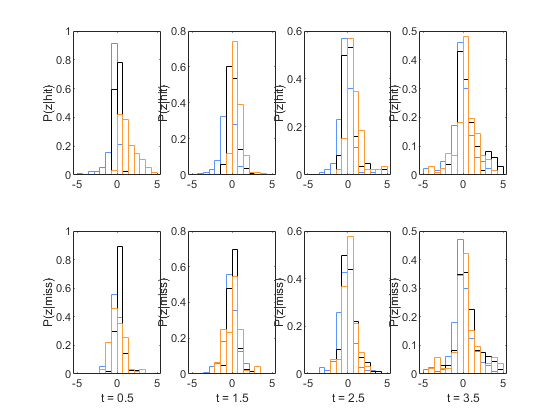

IM_dec = nan(2,lenwin);
IM_stim = nan(2,2,lenwin); % hits-miss, aud-tac, t
ed = linspace(-5,5,15); 
%ed = [-20,ed,20];
Ps2 = [1/2,1/4,1/4];

clf, hold off
a = 1;

for t1 = 1: lenwin
    t = t1 + 325;
    
    % Dec 
    IM_dec(1,t1) = get_IM(Zscore_hits_dec_s(:,:,t1),ed,Ps);
    IM_dec(2,t1) = get_IM(Zscore_miss_dec_s(:,:,t1),ed,Ps);

    
    % Stim
    IM_stim(1,1,t1) = get_IM(Zscore_hits_stim_s(1:3,:,t1),ed,flip(Ps2));
    IM_stim(2,1,t1) = get_IM(Zscore_miss_stim_s(1:3,:,t1),ed,flip(Ps2));
    IM_stim(1,2,t1) = get_IM(Zscore_hits_stim_s(3:5,:,t1),ed,Ps2);
    IM_stim(2,2,t1) = get_IM(Zscore_miss_stim_s(3:5,:,t1),ed,Ps2);

    if rem(t1,50) == 0 %plot
        
        subplot(2,4,a)
        histogram(Zscore_hits_dec_s(1,~isnan(Zscore_hits_dec_s(1,:,t1)),t1),ed,"EdgeColor",color_class("Aud"),"FaceColor","none","Normalization","pdf")
        hold on
        histogram(Zscore_hits_dec_s(2,~isnan(Zscore_hits_dec_s(2,:,t1)),t1),ed,"EdgeColor",color_class("NoS"),"FaceColor","none","Normalization","pdf")
        histogram(Zscore_hits_dec_s(3,~isnan(Zscore_hits_dec_s(3,:,t1)),t1),ed,"EdgeColor",color_class("Tac"),"FaceColor","none","Normalization","pdf")
        hold off        
        ylabel("P(z|hit)")        
        
        subplot(2,4,a+4)
        histogram(Zscore_miss_dec_s(1,~isnan(Zscore_miss_dec_s(1,:,t1)),t1),ed,"EdgeColor",color_class("Aud"),"FaceColor","none","Normalization","pdf")
        hold on
        histogram(Zscore_miss_dec_s(2,~isnan(Zscore_miss_dec_s(2,:,t1)),t1),ed,"EdgeColor",color_class("NoS"),"FaceColor","none","Normalization","pdf")
        histogram(Zscore_miss_dec_s(3,~isnan(Zscore_miss_dec_s(3,:,t1)),t1),ed,"EdgeColor",color_class("Tac"),"FaceColor","none","Normalization","pdf")
        hold off
        ylabel("P(z|miss)")
        xlabel("t = " + num2str(tv(t1+326)))        
        a = a + 1;
    end
end

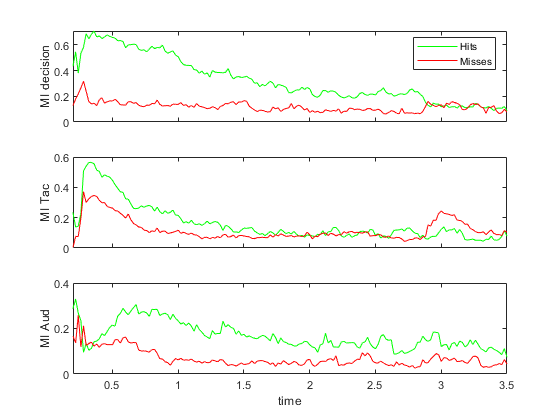

clf, hold off
subplot(3,1,1)
plot(tv(wind),IM_dec(1,:),"Color","green")
hold on
plot(tv(wind),IM_dec(2,:),"Color","red")
xlim([0.2,3.5])
xticklabels([])
ylabel("MI decision")
legend("Hits","Misses")

subplot(3,1,2)
plot(tv(wind),squeeze(IM_stim(1,2,:)),"Color","green")
hold on
plot(tv(wind),squeeze(IM_stim(2,2,:)),"Color","red")
xticklabels([])
xlim([0.2,3.5])
ylabel("MI Tac")

subplot(3,1,3)
plot(tv(wind),squeeze(IM_stim(1,1,:)),"Color","green")
hold on
plot(tv(wind),squeeze(IM_stim(2,1,:)),"Color","red")
xlabel("time")
xlim([0.2,3.5])
ylabel("MI Aud")

%saveas(gcf, "IM_zscore.svg")

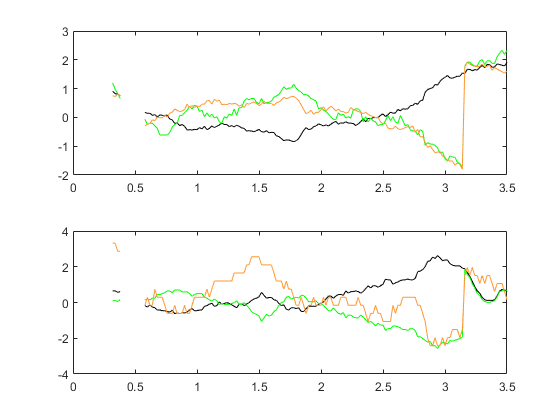

n = example_neurons(5);
clf, hold off
subplot(2,1,1)
plot(tv(wind),squeeze(Zscore_hits_stim_s(3,n,:)),"Color",color_class("NoS"))
hold on
plot(tv(wind),squeeze(Zscore_hits_stim_s(4,n,:)),"Color","green")
plot(tv(wind),squeeze(Zscore_hits_stim_s(5,n,:)),"Color",color_class("Tac"))
subplot(2,1,2)
plot(tv(wind),squeeze(Zscore_miss_stim_s(3,n,:)),"Color",color_class("NoS"))
hold on
plot(tv(wind),squeeze(Zscore_miss_stim_s(4,n,:)),"Color","green")
plot(tv(wind),squeeze(Zscore_miss_stim_s(5,n,:)),"Color",color_class("Tac"))

function Fr = freq(D,pas,ven, mini, maxi)
[xd, ~] = size(D);
num = fix(ven/pas);
tv = mini:pas:maxi;
D = fix((D-mini)/pas)+1;
Fr = zeros(xd,length(tv));
for ens = 1 : xd
    for x = 1 : (length(tv)-num)
        B = (D(ens,:)>x-num & D(ens,:)<=x);
        suma = sum(B(:));
        Fr(ens,x+num) = suma/ven;
    end
end
end

function IM = get_IM(A, ed, Ps)
IM = 0;

Pt = histcounts(A(~isnan(A)),ed,"Normalization","probability");

for i = 1:size(A,1)
    Prs = histcounts(A(i,~isnan(A(i,:))), ed,"Normalization","probability");
    IM = IM + Ps(i) * sum(Prs.*log2(Prs./Pt),"omitnan");
end
end





